# MATLAB

# Image-Based Defect Detection for Manufacturing Inspection

Team Members:

Christian Loriega

Carlos Tapia

Destiny Aguillon

# Abstract

    Modern manufacturing inspection systems must provide both reliable classification decisions and understandable evidence explaining why a component was accepted or rejected. Although deep-learning models can achieve strong classification performance, their predictions may be difficult for engineers and operators to interpret. In comparison, classical image-processing methods can generate measurable and traceable evidence, but they may be sensitive to variations in lighting, texture, orientation, and image quality.

    We've developed a hybrid manufacturing inspection system for screw components using classical image processing and transfer learning. Classical image processing generates visual defect evidence and quantitative measurements, while a ResNet-18 classifier produces the primary PASS or FAIL decision. The system is evaluated using image batch testing, confusion matrices, yield statistics, defect rates, and robustness testing under simulated lighting, blur, and noise variations.

    Our motivation stemmed from the need to combine the strengths of both approaches. The ResNet-18 classifier provides the primary PASS or FAIL decision, while the classical image-processing pipeline identifies suspicious geometric features and produces evidence overlays and numerical measurements. This hybrid approach improves transparency, supports debugging, and provides useful information for validating inspection decisions.

    Our team specifically targeted screw components because they can contain subtle manufacturing defects, including tip damage, scratches, and thread damage. Developing an automated and repeatable inspection pipeline demonstrates how computer vision and artificial intelligence can support manufacturing quality control.

# a. Problem Definition and Proposed Solution

**Problem Statement: **

    The objective of this project is to create an automated image-based inspection system using MATLAB, that identifies defective screw components. The system must classify each inspected part as PASS or FAIL while also generating visual and numerical evidence that explains what the inspection system detected.

**Requirements:**

- Standardize and preprocess each input image.

- Identify and quantify suspicious visual evidence.

- Classify parts as PASS or FAIL using a pretrained neural network.

- Return a classification confidence score.

- Produce evidence overlays and metric data.

- Evaluate performance on a repeatable test dataset.

- Test robustness under brightness, blur, and noise variation.

**Dataset: **MVTec AD - Screw Dataset

**Software: **MATLAB R2026a, Deep Learning Toolbox, Image Processing Toolbox

**Constraints:**

- MVTec AD's training folder only contains good images, indicating further variation may be beneficial for advanced accuracy.

- MVTec AD is relatively small for deep-learning training.

- Images may vary in orientation and brightness, indicating further filtering needed.

**Proposed Solution:**

**Hybrid manufacturing inspection system combining AI and classical image processing.**

Flow Diagram - 

# b. Project File Organization

# c. Function Reference

    The hybrid inspection system is organized using a modular software architecture using custom dedicated MATLAB functions located in the **/src **directory. Each function performs a specific task within the inspection pipeline, making the system easier to understand, maintain, and extend. The following reference summarizes the purpose, inputs, outputs, and primary operations of each function. Additionally, the functions are organizer in this reference in order of creation and separated by their responsibilities.

**File Location:** `/src`

## `Data Management:`

#### loadDataset

Purpose:

- Loads the MVTec AD dataset into a single MATLAB imageDatastore by combining the training and testing image folders while automatically assigning labels based on folder name.

Key Operations:

- Verifies that the dataset directory exists.

- Reads images from both the train and test folders.

- Automatically assigns labels from the folder names.

- Combines all images into a single imageDatastore for later preprocessing, training, and evaluation.

Input:

- **datasetFolder** - Path to the root directory of the selected MVTec AD object dataset.

Output:

- **imds** - Combined imageDatastore containing all images and their associated labels.

#### exploreDataset

Purpose:

- Provides a visual and statistical overview of the dataset by displaying class distributions, dataset statistics, and randomly selected sample images. This function is intended for exploratory data analysis before model training,

Key Operations:

- Displays the number of images and defect classes.

- Summarizes the number and percentage of images in each class.

- Generates bar graph for class distribution.

- Displays random sample images with corresponding labels.

Input:

- **imds** - MATLAB imageDatastore containing the dataset images and labels.

Output:

- No output variables, simply displays statistics, plots, and sample images.

## Image Preprocessing:

#### preprocessImage

Purpose:

- Standardizes the input image for the hybrid inspection system by resizing it to the network input dimensions and generates both RBG and grayscale versions for AI classification and classical image processing.

Key Operations:

- Resizes input image to 224 x 224 pixels.

- Ensures the image contains three color channels (Red, Green, Blue) for compatibility with ResNet-18.

- Converts to image to grayscale for later classical vision.

Input:

- **inputImage** - Original input image of intended part.

Output: 

- **rgbImage **- Standardized RGB image used for AI classification.

- **grayImage** - Grayscale image used for classical image processing and evidence extraction.

## Classical Vision:

#### detectManipulatedFront

Purpose:

- Detects front-tip defects on a screw image using classical image processing functions and techniques. The function hones in on the screw tip and extracts geometric evidence, evaluates predefined ed inspections rules, and generates both quantitative measurements and a visual inspections overlay. This function implements the 'manipulated_front' defect class from the MVTec AD dataset and serves as the first classical defect detector within the hybrid inspection system.

Key Operations:

- Segments and isolates the screw from the background.

- Aligns and auto-standardizes the screw orientation.

- Identifies the front-tip inspection region and crops it as a region of interest.

- Measures geometric features and describes the screw tips as pixels.

- Applies rule-based inspection thresholds to determine a baseline PASS/FAIL decision.

Input:

- **grayImage** - Preprocessed grayscale image of the screw.

Output:

- **overlay** - Annotated inspection image showing the analyzed tip region and detected evidence.

- **metrics **- Structure containing extracted geometric measurements and rule evaluations results.

- **baselineDecision **- Classical image PASS/FAIL decision based on defined inspection rules.

#### extractEvidence

Purpose:

- Acts as the central evidence extraction module for the classical vision system. It calls the appropriate defect detection algorithm, and returns he corresponding visualization and baseline inspection result.

Key Operations:

- Routes the input image to the appropriate classical defect detector (detectManipulatedFront).

- Returns evidence overlay, extracted measurements, and rule-based inspection decision. 

Input:

- **grayImage **- Preprocessed grayscale image of the screw.

Output:

- **overlay** - Annotated inspection image showing the analyzed tip region and detected evidence.

- **metrics **- Structure containing extracted geometric measurements and rule evaluations results.

- **baselineDecision **- Classical image PASS/FAIL decision based on defined inspection rules.

## AI Classification:

#### classifyPart

Purpose:

- Classifies an input screw image as PASS or FAIL using our trained ResNet-18 transfer learning model. The function preprocesses the image, runs the network prediction, and returns AI's predicted label and confidence in the prediction. The network uses weights learned from ImageNet and fine-tuned during training to recognize manufacturing defects.

Key Operations:

- Utilizes preprocessImage function to preprocess the input image to require the 224 x 224 RGB format for ResNet-18.

- Creates an augmentedImageDatastore compatible with ResNet-18.

- Generates class scores using the trained network.

- Converts class scores into PASS/FAIL label (ex. [0.98 0.02] -> ["PASS" "FAIL]).

- Returns highest class score as prediction confidence.

Input:

- **net** - Trained ResNet-18 network used for PASS/FAIL classification.

- **inputImage** - Original image of the screw to be classified.

Output:

- **aiLabel** - Predicted class label, PASS or FAIL.

- **aiScore** - Highest predicted class score, represents networks confidence score in its decision.

## Hybrid Inspection:

#### inspectPart

Purpose:

- Executes the complete hybrid inspection pipeline for a single input image by combining ResNet-18 classification with classical image processing. The function returns the AI prediction, classical evidence, and final confidence-based hybrid decision.

Key Operations:

- Loads our trained ResNet-18 model using a persistent variable.

- Preprocesses and standardize input image using preprocessImage function

- Performs AI-based PASS/FAIL classification using classifyPart function.

- Extracts classical evidence and geometric evidence using extractEvidence function.

- Returns both AI and classical evidence for a hybrid analysis.

Input:

- **inputImage** - Original image of the part to be inspected.

Output:

- **finalLabel** - Final PASS/FAIL decision produced by the confidence-based hybrid fusion rule.

- **aiLabel** - PASS/FAIL prediction produced by the ResNet-18 classifier.

- **confidenceScore** - AI confidence score associated with the prediction. 

- **evidenceOverlay** - Annotated image showing the detected classical evidence. 

- **evidenceMetrics** - Structure containing extracted geometric measurements.

- **baselineDecision** - PASS/FAIL decision produced by the classical inspection pipeline.

## Robustness Testing:

#### applyDistortion

Purpose:

- Applies a specific image distortion to simulate common manufacturing inspection variations. This function is used to evaluate the robustness of the hybrid inspection system under an assortment of imaging conditions.

Key Operation:

- Applies the selected image distortion.

- Supports multiple distinct distortion types through switch-case structure.

- Returns the distorted image.

Input:

- **inputImage** - Original input image to be distorted.

- **distortionType** - Type of distortion to apply (none, brightness, blur, noise)

Output:

- **distortedImage** - Image after applying distortion.

# 1. Dataset Exploration and Organization

## **Task 1**

## **1.1 Dataset Selection**

    The MVTec AD screw dataset was selected because it represents a realistic industrial inspection problem involving small, geometric surface defects. The dataset is comprised of **good, manipulated_front, scratch_neck, scratch_head, thread_side, and thread_top **classes**.**

    A focused subset of the dataset was created by selecting the **good, manipulated_front, and scratch_neck **classes**.** These classes define the PASS and FAIL categories used throughout the inspection pipeline. These classes were chosen because they are the most representative defects found in screws in manufacturing.

**Inspection Labels:**

PASS - 'good'

FAIL - 'manipulated_front', 'scratch_head', 'scratch_neck', 'thread_side', 'thread_top'

## 1.2 Dataset Preparation

    Dataset preparation takes place in **'A_prepare_data'.** The **loadDataset** function imports the images into an imageDatastore with their corresponding labels, while the **exploreDataset** function visualizes the dataset and class distribution. The selected classes (good, manipulated_front, and scratch_neck) are then filtered and converted into binary inspection labels, where good is assigned PASS and the defect classes are assigned FAIL.

    Finally, the script summarizes the dataset size, shows a montage of images, outputs class distribution via bar graph and table, and provides a PASS-to-FAIL ratio.


Data Preparation Summary
Dataset          : MVTec AD
Part Type        : screw
Dataset Location : C:\Users\protu\OneDrive\Desktop\GitHub\Image-Based-Defect-Detection-for-Manufacturing-Inspection\scripts\..\data\MVTec AD\screw

     DATASET SUMMARY

Total Images: 480

Number of Classes: 6

          Label          Count    Percent
    _________________    _____    _______

    good                  361     75.208 
    manipulated_front      24          5 
    scratch_head           24          5 
    scratch_neck           25     5.2083 
    thread_side            23     4.7917 
    thread_top             23     4.7917 



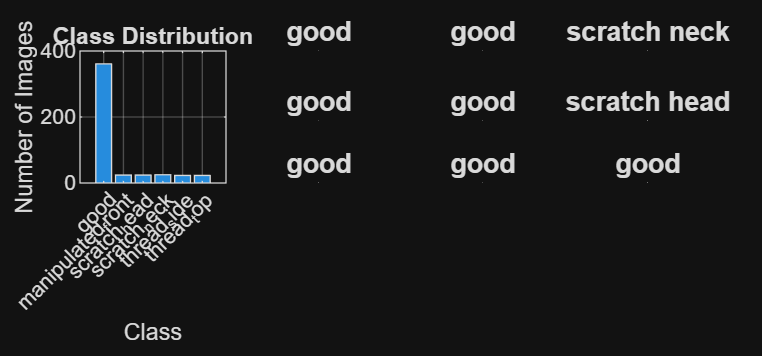


Final Project Scope
PASS Class       : good
FAIL Classes     : manipulated_front, scratch_neck
Focused Images   : 410
Focused Classes  : 3

Focused Dataset Distribution
----------------------------------------
          Label          Count
    _________________    _____

    good                  361 
    manipulated_front      24 
    scratch_neck           25 


Binary Classification Distribution
----------------------------------------
    Label    Count
    _____    _____

    FAIL       49 
    PASS      361 

PASS Images      : 361 (88.05%)
FAIL Images      : 49 (11.95%)
PASS-to-FAIL Ratio: 7.37 to 1


% Task 1 - Dataset Preparation
run("../scripts/A_prepare_data.m")

## 1.3 Dataset Characteristics

    The complete MVTec AD screw dataset contains 480 images distributed across six inspection categories. During the beginning of the project, we decided to focus on two class that we felt are the most common and representative manufacturing defects. For the scope of this project, the dataset was reduced to 410 images by selecting the good, manipulated_front, and scratch_neck classes. This creates a binary manufacturing inspection problem consisting of 361 PASS images and 49 FAIL images. The resulting PASS-to-FAIL ratio of approximately 7.4:1 indicates class imbalance and potential inconsistency. While this may seem inaccurate or unrepresentative, this simulates real manufacturing environments where defective parts occur much less frequently than acceptable parts.

# 2. Build a Single-Image Classical Inspection Pipeline

## Task 2

    The purpose of this section of the project was to develop a classical image-processing function that identifies and quantifies suspicious visual evidence in individual screw images. The design was aimed to aid the final AI classification decision by producing quantitative metrics and evidence overlays.

## 2.1 Image Preprocessing

    The preprocessing results come from our **'B_preprocess_data' **script, which acts as a simple demonstration for how the original screw image is converted into an RGB image and a grayscale image. Each input image is first processed using our **preprocessImage** function. The function produces two standard outputs:

- An RGB image resized to [224 224 3] for the ResNet-18 classifier.

- A grayscale image used by the classical vision algorithms.

    In this section, we'll only me using grayscale images since they simplify future thresholding, segmentation, texture analysis, and geometric measurement for our system.

% Task 2 - Image Preprocessing
run("../scripts/B_preprocess_data.m")

Image Preprocessing
Dataset          : MVTec AD
Part Type        : screw
Focused Classes  : good, manipulated_front, scratch_neck
Focused Images   : 410

Focused Dataset Distribution
----------------------------------------
          Label          Count
    _________________    _____

    good                  361 
    manipulated_front      24 
    scratch_neck           25 



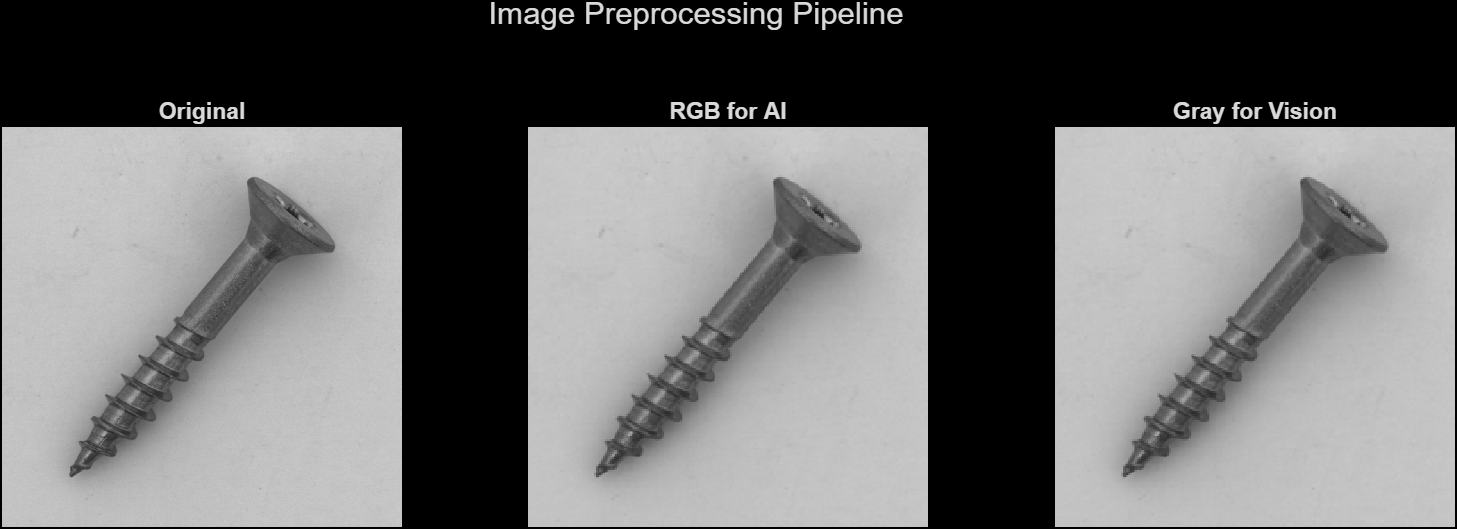

## 2.2 Scope

    After narrowing the scope of our inspection system, we developed two defect-specific classical vision functions.

- **detectManipulatedFront**

- **detectScratchedNeck**

    Each function automatically locates the relevant region of interest, extracts measurable defect data, and returns a rule-based PASS or FAIL decision.

## 2.3 Manipulated-Front Evidence

Workflow Diagram:

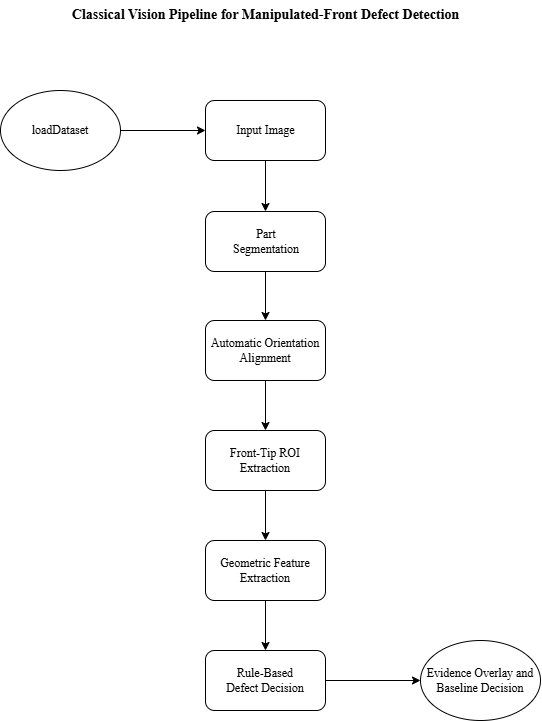

    The manipulated-front detector analyzes the geometry of the screw tip. First, the screw is segmented using *imbinarize, *and small background regions are removed using *bwareaopen*. Holes inside the screw are also removed using the *imfill *function.

    The largest connected region is treated as the screw. Its orientation is estimated using *regionprops*, and the screw is automatically rotated into a horizontal position. The width of both ends is then compared so that the narrow screw tip is consistently placed on the left. 

    The detector inspects approximately the front 20% of the screw, crops the rest of the screw out, and calculates the following measurements:

    These metrics describe the size, taper, and straightness of the screw tip. A manipulated tip may be too wide or narrow, contain an abrupt width change, or have an unstable centerline.

    A red line is shown in the evidence overlay representing the estimated centerline of the screw tip, calculated by averaging the foreground pixel locations in each image column to visualize tip straightness.

Three conservative rules are used: 

`ruleWidth = tipWidth >= 28 && tipWidth <= 39; `

`ruleSlope = maxSlope <= 2.5; `

`ruleStraight = centerDeviation <= 1;`

    The screw receives a baseline PASS only when all three rules pass. Otherwise, the detector returns FAIL.

    The evidence overlay displays the inspected tip region and the estimated centerline. A green region represents a baseline PASS, while a red region represents a baseline FAIL.

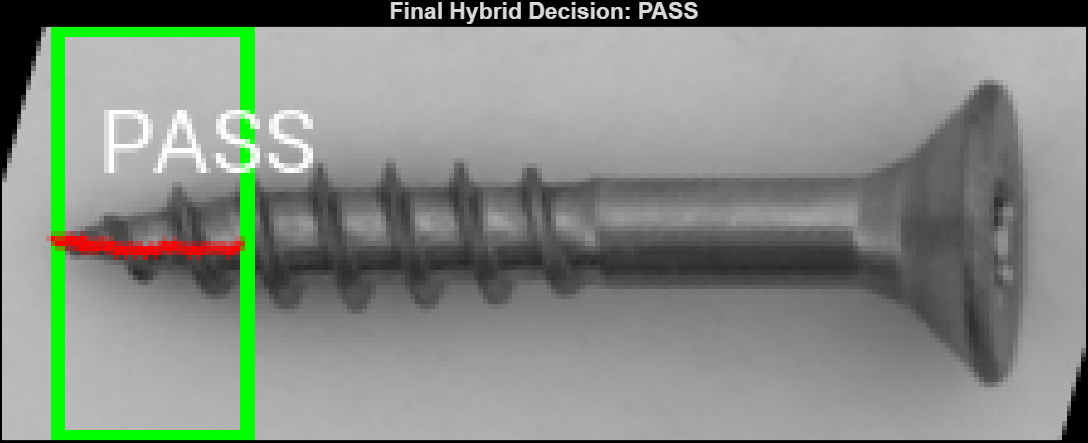

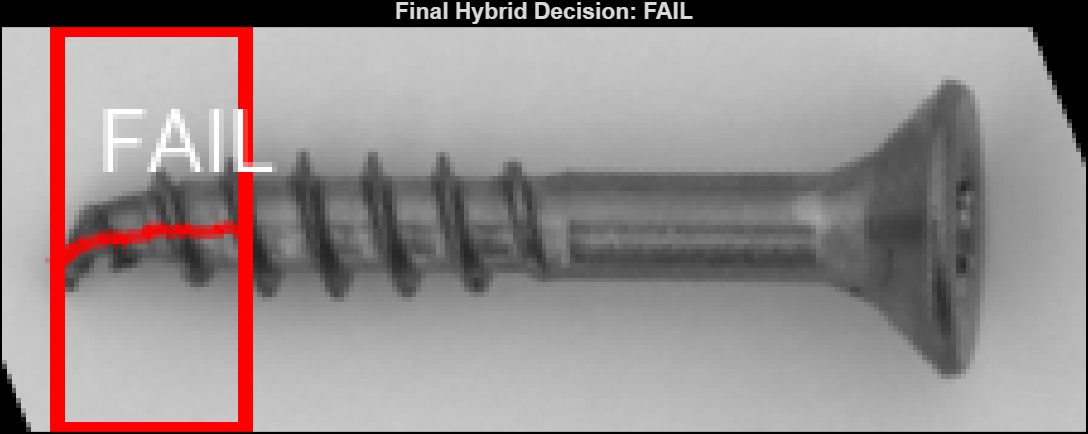

## 2.4 Scratch-Neck Evidence

Workflow Diagram:

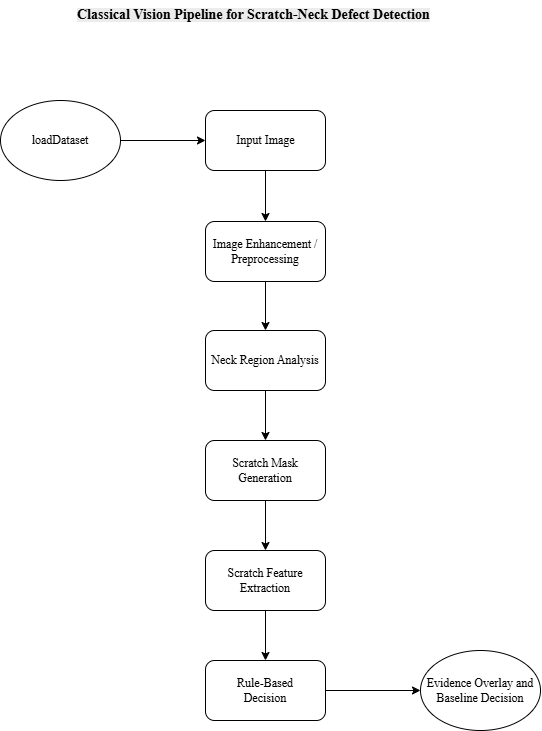

    The scratch-neck detector analyzes abnormal texture near the screw neck. The screw is segmented from the background, and the largest connected region is retained. The outer boundary of the screw is slightly eroded using the *imerode *function to prevent strong edge reflections from being classified as scratches.

    The main direction of the screw is calculated from the screw-mask pixel coordinates. This allows the algorithm to automatically locate the neck region without requiring a manually selected crop.

    Local texture variation is measured using *stdfilt*. Pixels with texture values significantly greater than the average neck texture are marked as initial scratch evidence. The mask is then cleaned using *bwareaopen*, *bwmorph*, and *imclose*.

    This algorithm considers candidate scratch regions and are filtered according to their area, length, elongation, and direction relative to the screw's axis.

    The scratch measurements are:

Ruling System:

`scratchDetected = ...`

`             scratchCount >= 1 && totalScratchArea >= 15 &&  largestScratchArea >= 10 &&  scratchRatio >= 0.004;`

    A rule-based decision is made using four conservative thresholds that evaluate the amount and size of the detected scratch evidence. The screw is classified as FAIL only when sufficient scratch evidence is present, reducing false detections caused by image noise or surface reflections.

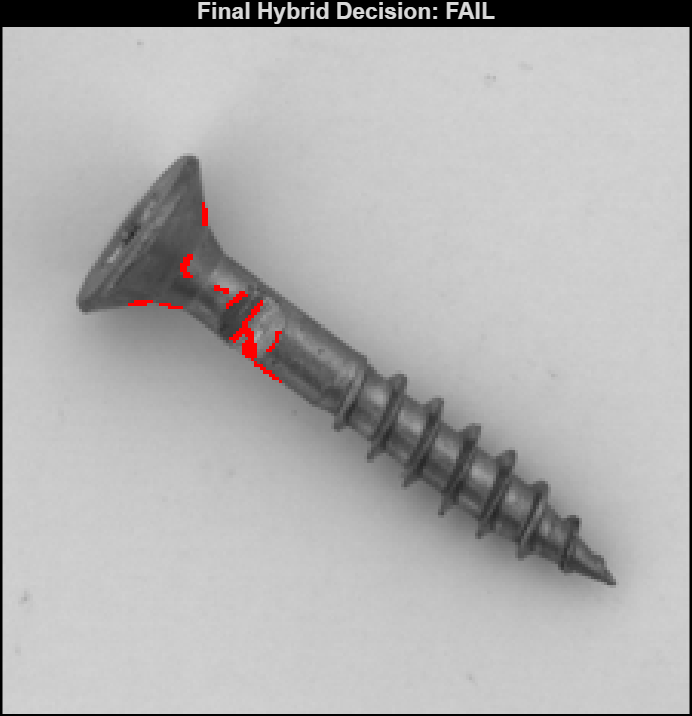

## 2.5 Combined Classical Evidence Extraction

    The final classical vision pipeline is integrated through the extractEvidence.m function, which combines the outputs of both the manipulated-front and scratch-neck detectors into a single inspection result. Rather than relying on one defect-specific algorithm, the function evaluates both detectors on the same preprocessed image and compares the strength of the extracted evidence.

    After validating the evidence, the function determines the most likely detected defect, selects the corresponding evidence overlay, and packages all measurements into a single metrics structure. This includes the final baseline decision, the individual detector decisions, and the geometric and texture measurements produced by each detector.

    Additionally, **'C_classical_evidence' **serves as a in depth testing platform for the manipulated-front screw class. The scripts outputs a full in depth process of how the algorithm operate:

- First it displays a region of interest using a bounding box.

- Then crops around the ROI.

- It displays a width profile going from columns left to right.

-  Secludes the tip region of the screw.

- Runs another width profile, this time on the tip region.

- Finally, displays relevant tip metrics, and makes a binary decision.

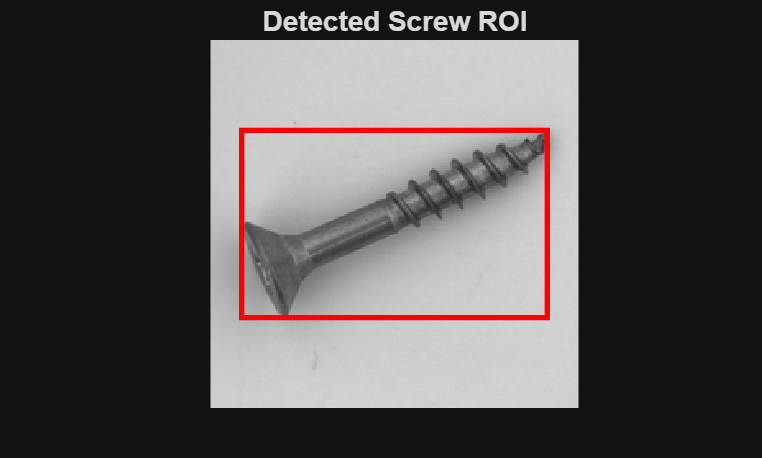

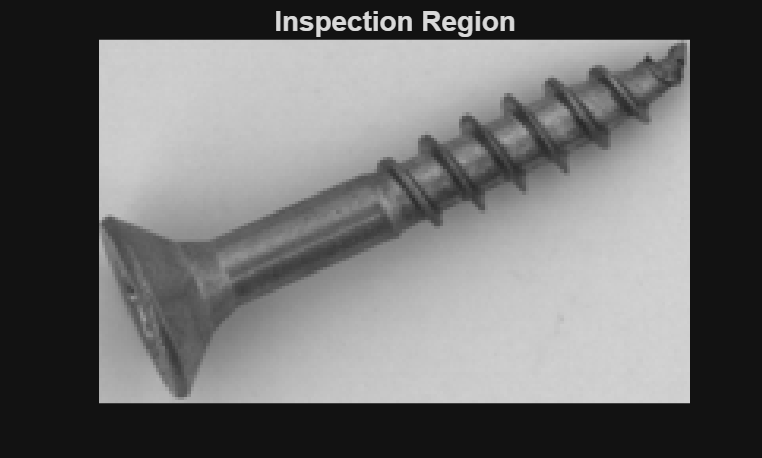

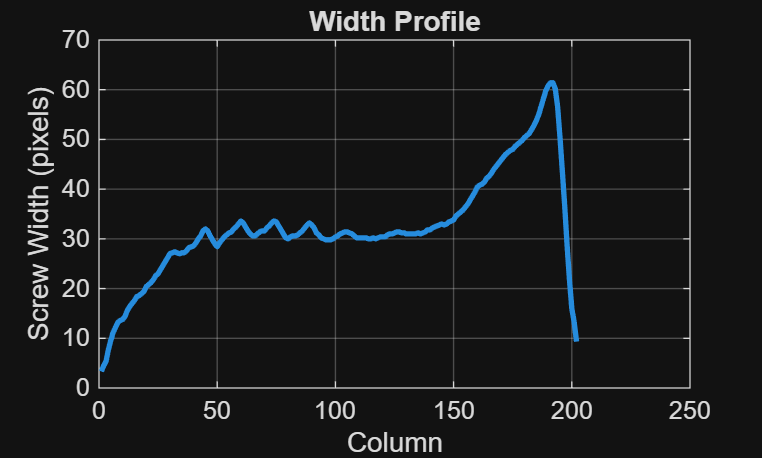

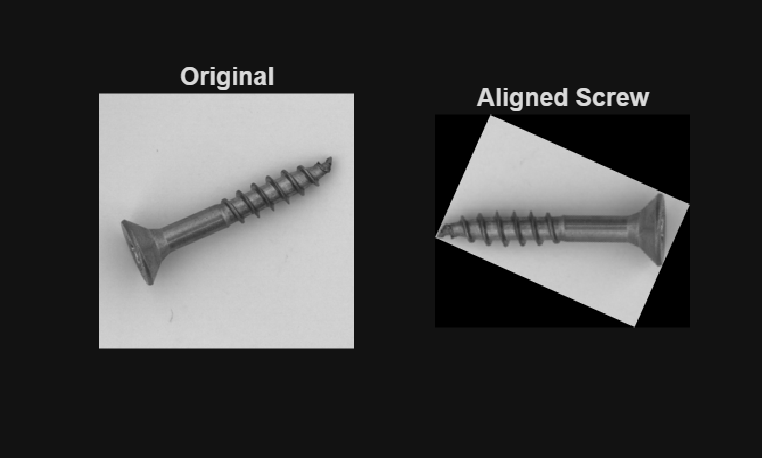

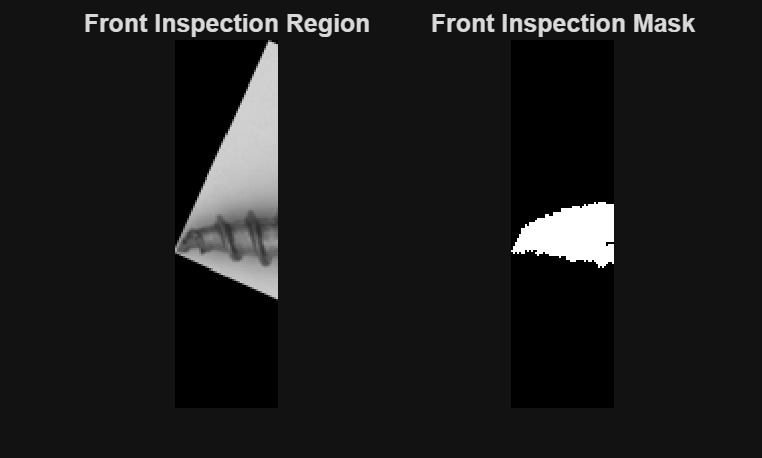

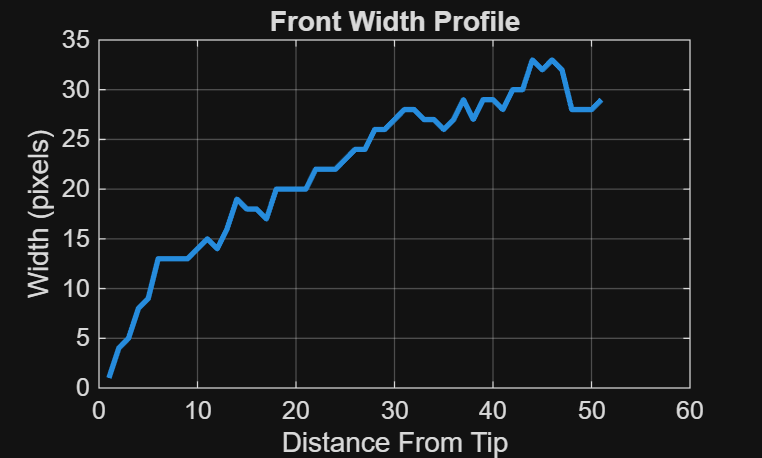

Tip Width       : 33 pixels
Tip Area        : 1114 pixels
Average Slope   : 1.35
Slope Variation : 0.82


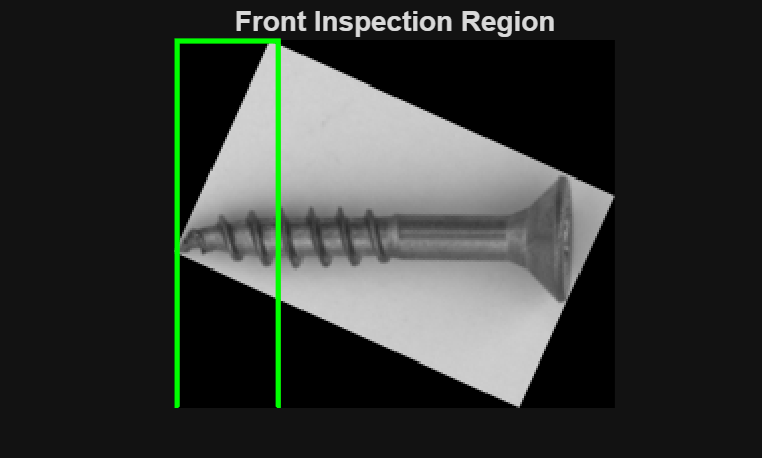


 Rule-Based Inspection Results
Tip Width        : 32.7 pixels
Average Slope    : 1.35
Center Deviation : 2.20 pixels

Rule Results
----------------------------
Tip Width     : true
Tip Taper     : false
Tip Straight  : false

Failed Rules : 2 / 3
Inspection Status : FAIL


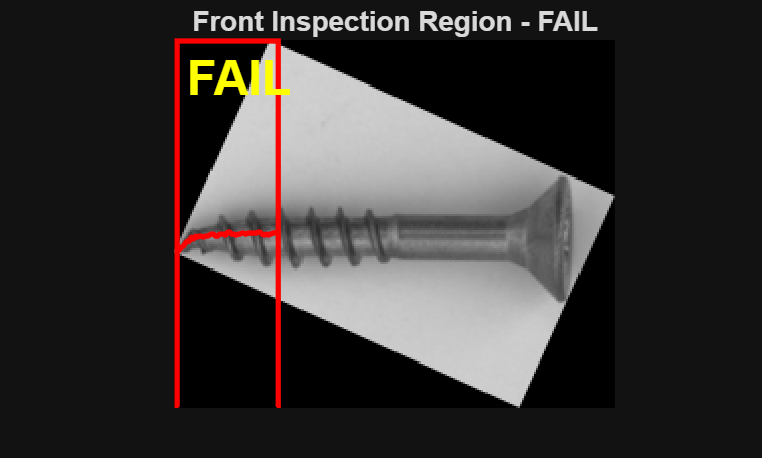

% Dedicated Manipulated_Front Testing Platform
run("../scripts/C_classical_evidence.m")

## 2.6 Role of Classical Vision in the Hybrid Inspection System

    Although the classical image-processing pipeline provides detailed metrics and visual evidence, it was not intended to serve as a complete standalone inspection system. A huge drawback to this classical system is that rule-based methods often require extensive threshold tuning and become increasingly difficult to maintain as additional defect types, lighting conditions, and manufacturing variations are introduced. Small changes in image quality or part appearance can require repeated adjustment of segmentation parameters and decision thresholds to maintain acceptable performance.

    Instead, the classical vision pipeline was designed to complement the AI classifier rather than compete with it. The extracted measurements, rule-based decisions, and evidence overlays provide evidence that help explain what the algorithm identified as suspicious, while the ResNet-18 classifier remains responsible for the primary PASS or FAIL decision.

# 3. Transfer Learning with ResNet-18

## Task 3

## 3.1 Why Transfer Learning Was Used

    Training a neural network from scratch to detect anything, much less hundreds of different types of manufacturing parts, is very challenging. This is why transfer learning was selected. Transfer learning is the action of taking a pretrained neural network and altering its weights and outputs to match your learning targets. Since the MVTec AD manufacturing dataset is relatively small compared to the datasets usually required to train a convolutional neural network from scratch, it made sense to utilize transfer learning.

    Additionally, ResNet-18 was a great pretrained neural network to work with as it's been trained on a large general-purpose dataset and already contains a lot of the learned weights capable of detecting useful visual patterns. Specifically, ResNet-18 has been trained with **ImageNet-1K dataset **1.28 million training images and 50,000 validation images across 1,000 weighted object categories.

    Some of the important patterns include:

- Edges

- Curves

- Corners

- Shapes

- Surface textures

- Complex object features

## 3.2 Network Weights and Transfer Learning

    A neural network contains many numerical parameters called weights. These weights determine how strongly the network responds to different visual features. Deeper layers combine these patterns into more complex visual features.

    During transfer learning, the network begins with its existing pretrained weights rather than random values. The original final classification layer, which was designed for the network’s previous classes, is replaced with a new output configured for two inspection classes:

- PASS

- FAIL

`net = imagePretrainedNetwork("resnet18", ``NumClasses=2``);`

    The pretrained layers provide the network’s starting visual knowledge, while the new classification output allows the model to learn the specific difference between acceptable and defective screw images. During training, the optimizer repeatedly updates the network weights to reduce classification error. 

## 3.3 Input Image Size and Data Augmentation

    ResNet-18 requires three-channel images with a consistent input size. Each screw image is resized to match the network input dimensions.

`inputSize = [224 224 3];`

The augmentedImageDatastore performs two important operations:

- It resizes each image to the dimensions expected by ResNet-18.

- It converts grayscale images into three-channel images when necessary.

`augTrain = augmentedImageDatastore(inputSize(1:2), imdsTrain, "ColorPreprocessing", "gray2rgb");`

    Data augmentation was applied to introduce small variations into the training images. The augmentation included limited rotation and translation to simulate minor inconsistencies  in screw position and orientation.

    The selected transformations included:

- Rotations of approximately ±10 degrees

- Horizontal translations of approximately ±5 pixels

- Vertical translations of approximately ±5 pixels

    Data augmentation helps prevent the network from memorizing the exact position and orientation of the training images. Instead, it encourages the model to learn defect-related visual features that remain meaningful under small pose variations. However, the augmenters range was kept limited and consistent as excessive rotation and manipulation could create unrealistic circumstances for the screws.

## 3.4 Training Configuration

    The model was trained using the Adam optimizer. Adam stands for, Adaptive Moment Estimation, which automatically adjusts how much each weight changes during training.

`options = trainingOptions("adam", "InitialLearnRate", selectedLearningRate, "MaxEpochs", ... selectedEpochs, "MiniBatchSize", selectedBatchSize,  "ValidationData", augValidation, ...`

`Plots", "training-progress");`

Each option affects how the network weights are updated during training.

## 3.5 Training and Validation

    The training dataset is used to calculate the classification error and update the network weights. The validation dataset is processed during training but is not used to update the weights. Its purpose is to estimate how well the model performs on images it has not directly learned from.

The training-progress plot provides:

- Training loss

- Validation loss

- Training accuracy

- Validation accuracy

    A decreasing training loss indicates that the network is improving its predictions on the training data. Validation accuracy provides a stronger indication of whether those improvements generalize to unseen images. Overfitting is when a neural network learns the training images too specifically or memorizes images instead of learning general visual features that apply to new data. A large difference between training and validation performance may indicate overfitting. For example training loss continuously decreasing while validation loss increasing creating a widened gap.

     The focused PASS/FAIL dataset is randomly divided into training, validation, and original test sets. These datastores are saved in **focused_dataset_split.mat**, in **/models**, as *imdsTrain*, *imdsVal*, and *imdsTes*t.

`[imdsTrain, imdsTemp] = splitEachLabel(imds, 0.8, "randomized"); `

`[imdsVal, imdsTest] = splitEachLabel(imdsTemp, 0.5, "randomized");`

`...`

`splitFile = fullfile(modelsFolder, "focused_dataset_split.mat"); save(splitFile, "imdsTrain", "imdsVal", "imdsTest");`

    Reusing these saved datastores ensures that all subsequent evaluation and robustness experiments are performed on the same dataset split, allowing fair performance comparisons.

## 3.6 Transfer Learning Results

### Baseline Experiment:

Objective:

- Establish a baseline performance for transfer learning using a pretrained ResNet-18 model with default Adaptive Moment Estimation optimizer settings. The resulting performance metrics provide a benchmark for evaluating the effects of later adjustments.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.001 (Default)

- Epochs: 10

- Batch Size: 32

Results:

- Test Accuracy: 75%

- Training Time: 5 min 44 s

- Final Training Loss: 0.9723

- Final Validation Loss: 0.5474

Observations:

- The training loss generally decreased throughout training, while the validation loss exhibited several fluctuations.

- Potential overfitting due to larger gaps and validation loss fluctuation.

Summary:

- The baseline ResNet-18 model achieved a 75.0% test accuracy using the default Adam learning rate (0.001). While the training loss generally decreased over time, the validation loss showed several fluctuations during training. This experiment establishes a performance benchmark for comparison with later optimization experiments.

Training Graph:

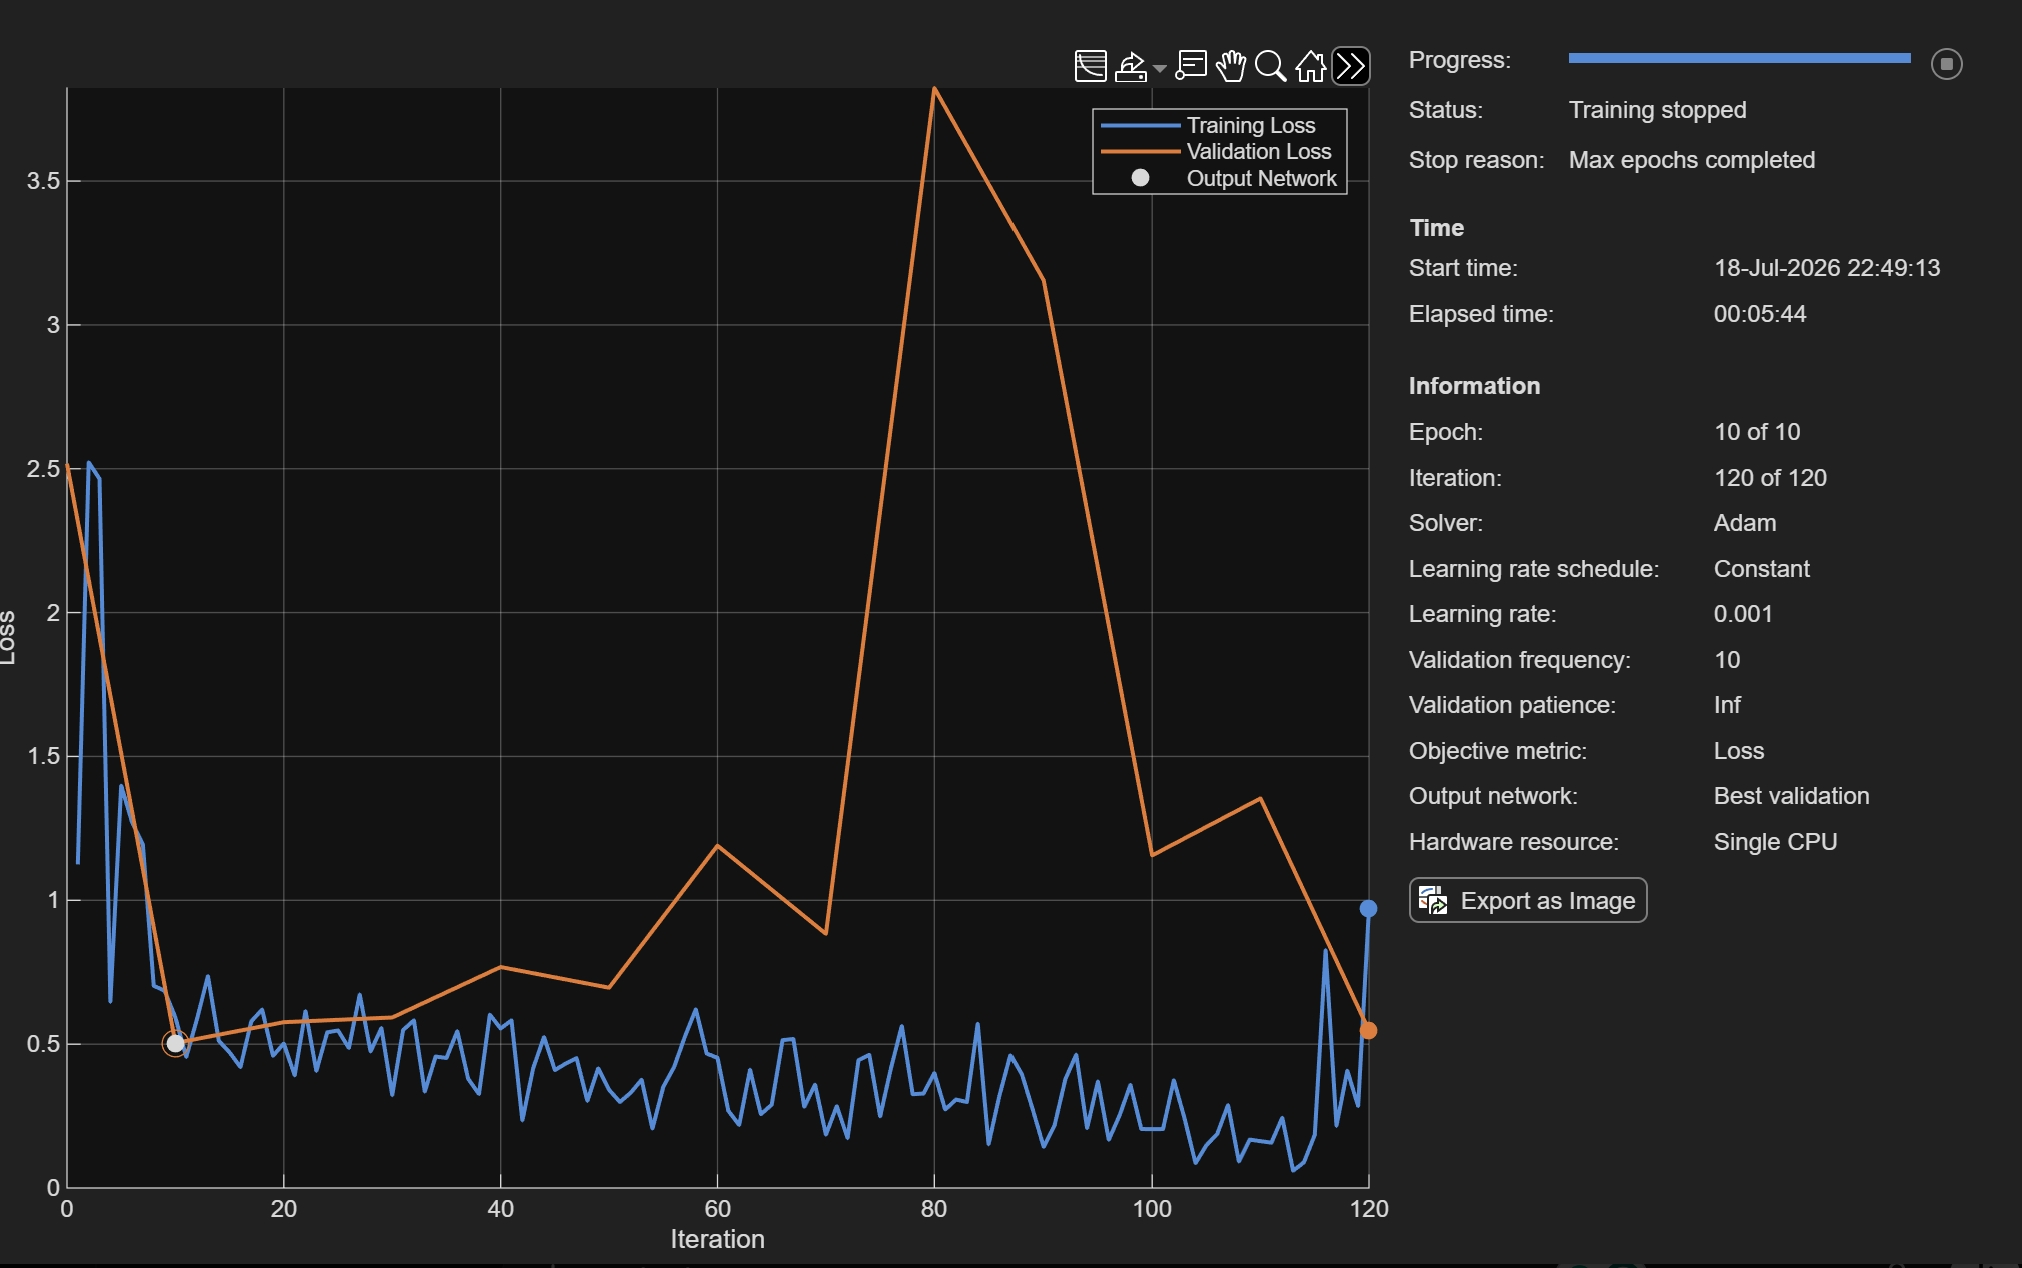

### Experiment 2:

Objective:

- Evaluate whether decreasing the initial learning rate from the default Adam setting to 0.0001 improves the performance of the ResNet-18 transfer learning model.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.0001

- Epochs: 10

- Batch Size: 32

Results:

- Test Accuracy: 87.5%

- Training Time: 4 min 39 s

- Final Training Loss: 0.0839

- Final Validation Loss: 0.3183

Observations:

- A lower learning rate improved generalization and increased defect detection performance from 75% to 87.5%.

- Final training and validation loss are reasonably close indicating this model is well generalized.

Summary:

- By reducing the initial learning rate to 0.0001, the model was able to produce a smoother optimization and classification performance. The training loss steadily decreased through the 10 epochs, indicating that the network continued learning without much instability. While the model's validation loss briefly increased during Epoch 8 and 9, it recovered by the end of the training. This fluctuation was likely due to the validation set only containing 10%, or 48 images of the dataset. Similarly, this peak in the validation loss are observed in both Experiment 2 and the Baseline Experiment, further suggesting this was the cause of the imbalance of the dataset. The final model achieved 87.5% test accuracy, correctly identifying 11 of the 12 defective parts.

Training Graph:

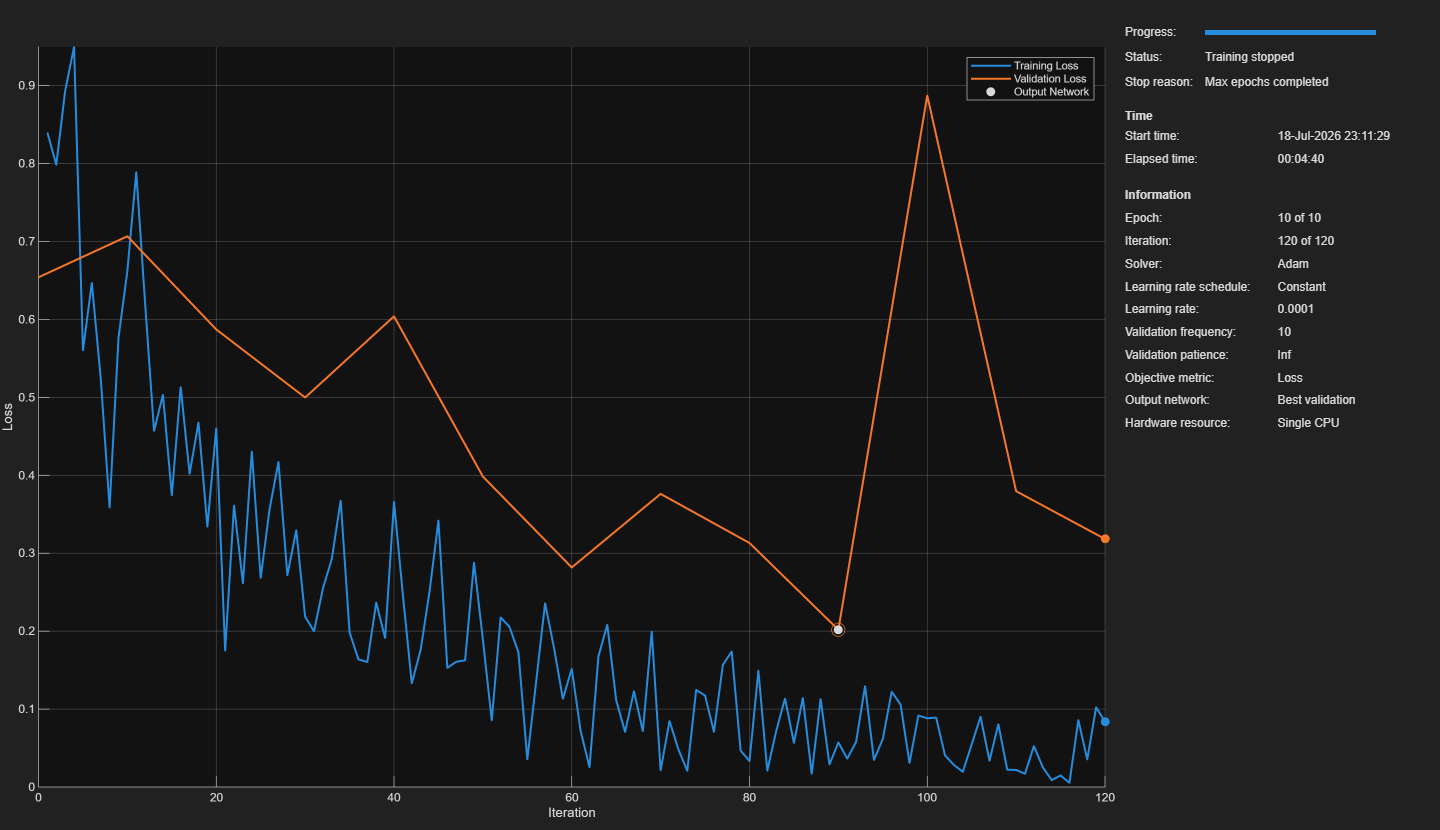

Confusion Matrix:

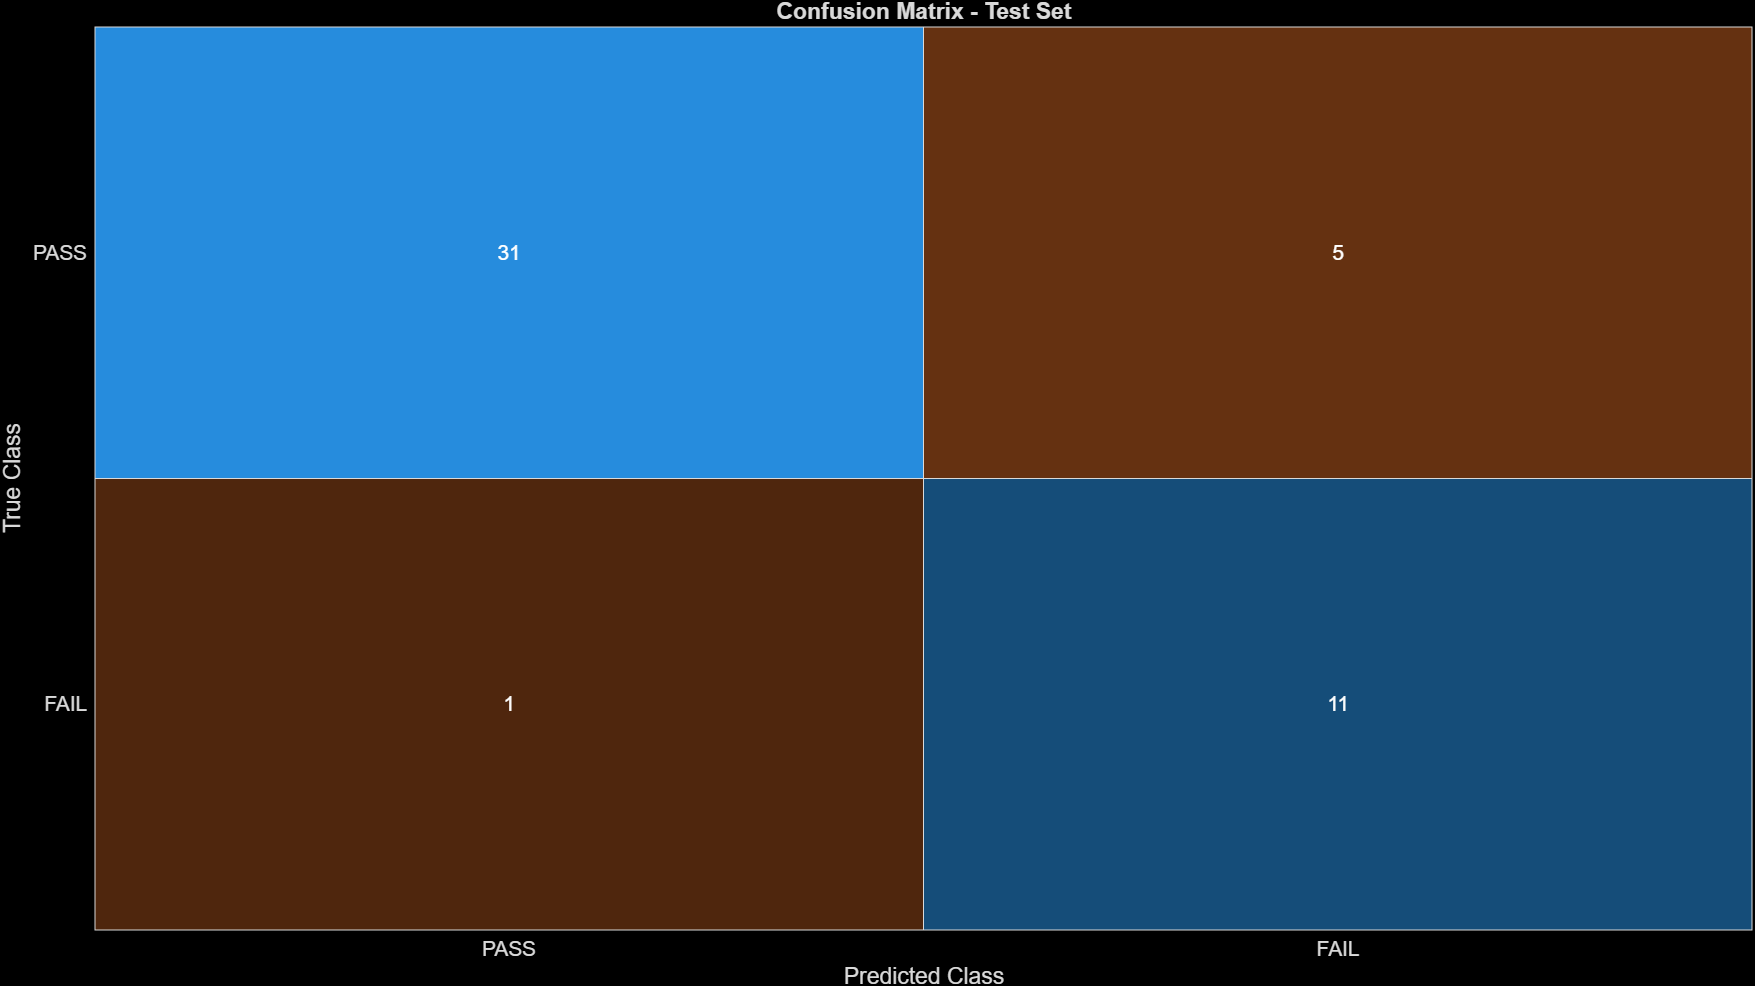

### Experiment 3:

Objective:

- Evaluate whether the number of training epochs from 10 to 20 further improves the performance of the ResNet-18 transfer learning model.

- Monitoring precision, recall, and F1-score as evaluation metrics.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.0001

- Epochs: 20

- Batch Size: 32

Results:

- Test Accuracy: 91.67%

- Training Time: 9 min 41 s

- Final Training Loss: 0.0085479

- Final Validation Loss: 0.15461

- Precision: 0.833

- Recall: 0.833

- F1-score: 0.833

Observations:

- Increasing the number of training epochs from 10 to 20 improved the model's overall classification performance, increasing the test accuracy from 87.5% to 91.67%.

- The training loss steadily decreased throughout training, reaching a final values of 0.0085, indicating that the network continued to learn with the additional epochs.

- While the validation loss fluctuated during several epochs, it decreased to a final value of 0.1546 by the end of training suggesting the model maintained good generalization. 

- The model achieved a precision, recall, and F1-score of 0.833 for the FAIL class demonstrating balanced performance in detecting defective parts while limiting false positive and negatives.

- Approximately double the training time due to double the epochs.

Summary:

- Increasing the maximum number of training epochs from 10 to 20 allowed ResNet-18 to further optimize and learn features after reducing the learning rate. The larger epochs increased the amount of times the network saw the training data set. These results show that the network benefited from additional training time without substantial overfitting.

Training Graph:

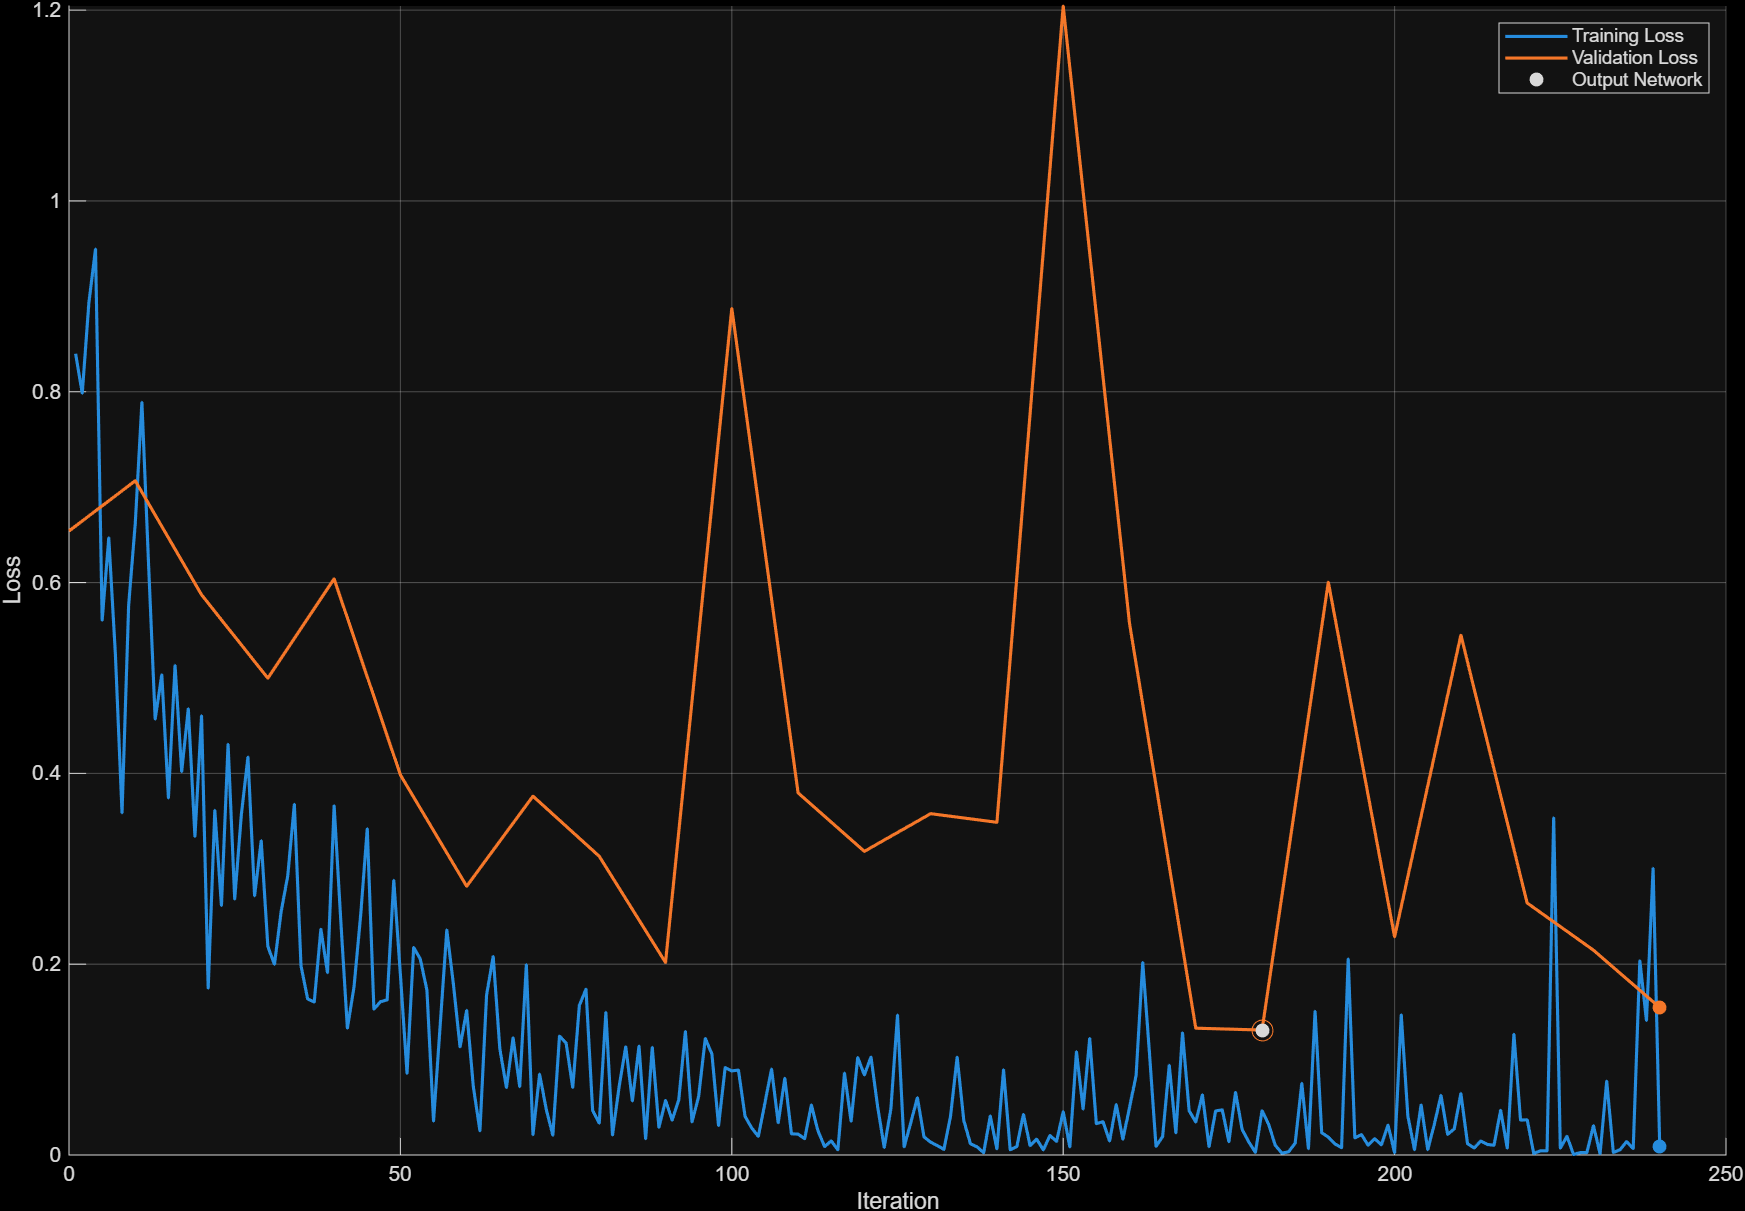

Confusion Matrix:

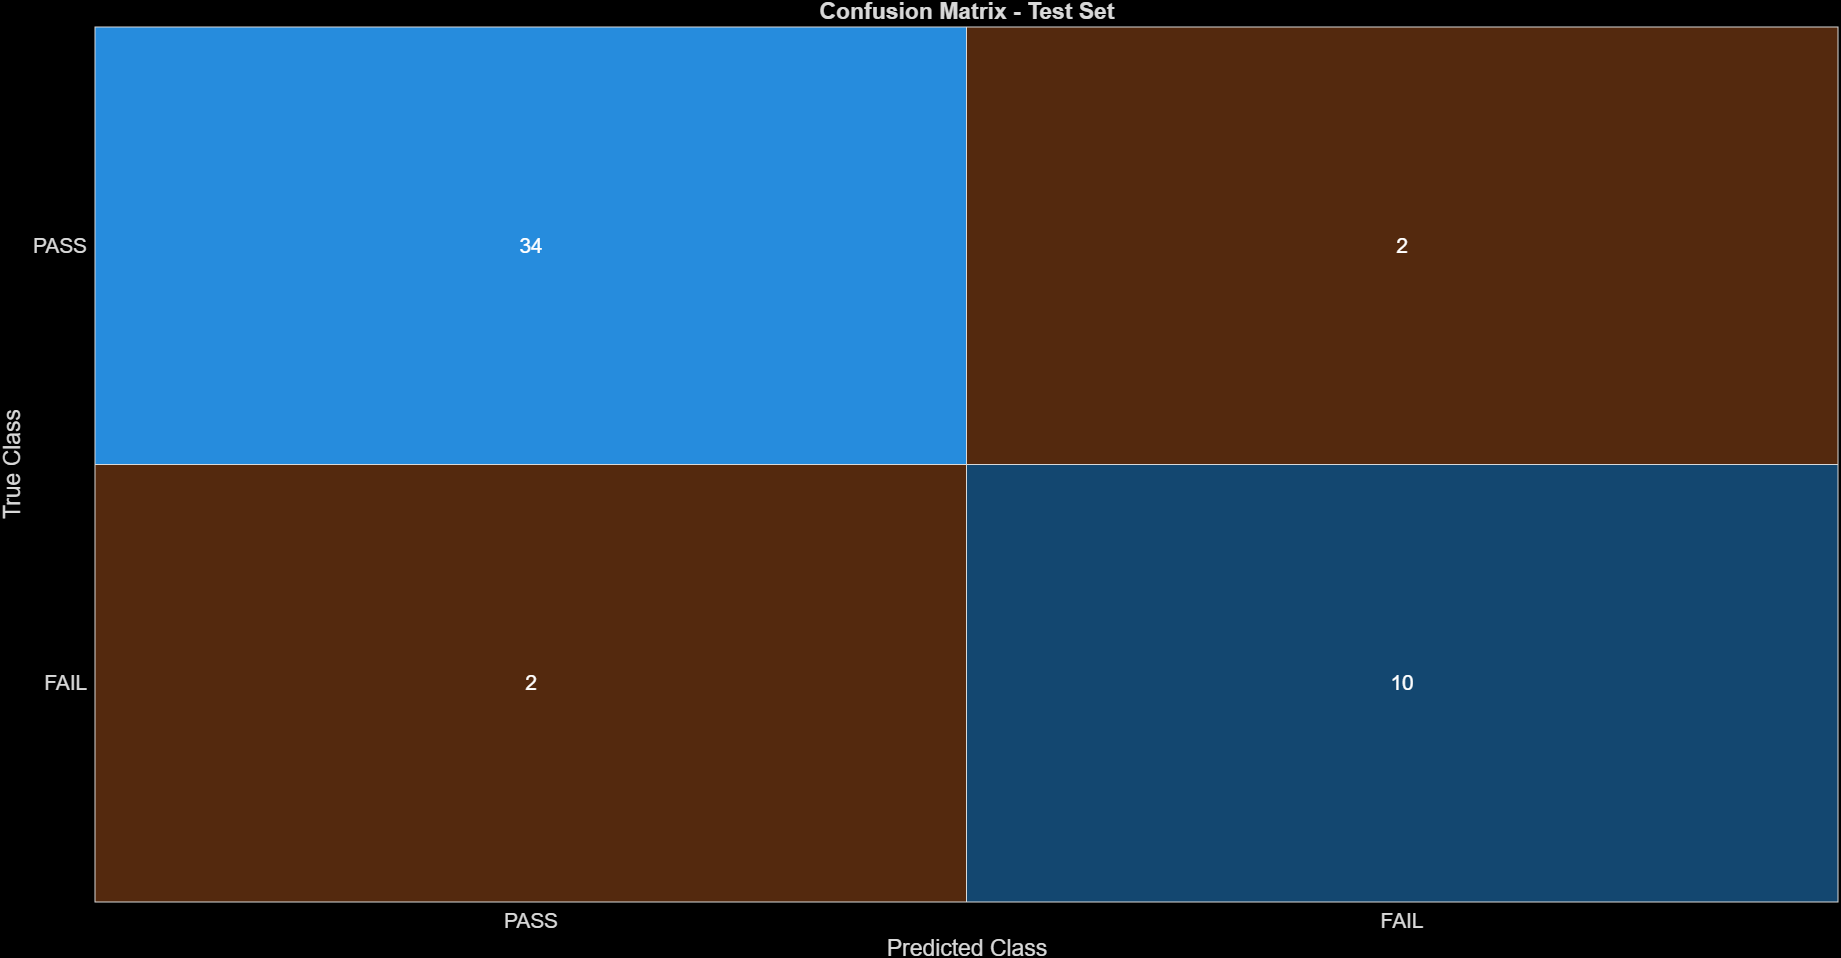

### Experiment 4:

Objective:

- Evaluate whether training ResNet-18 using only the defect categories targeted by the hybrid inspection system (`manipulated_front` and `scratch_neck`) improves classification performance. The original MVTec AD screw dataset was filtered to include only `good`, `manipulated_front`, and `scratch_neck` images before converting the labels to PASS/FAIL. Model performance was evaluated using accuracy, precision, recall, and F1-score.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.0001

- Epochs: 20

- Batch Size: 32

- Dataset**:** Filtered MVTec AD Screw where, PASS: `good, F`AIL: `manipulated_front`, `scratch_neck`

Results:

- Test Accuracy: 95.12%

- Training Time: 7 min 37 s

- Final Training Loss: 0.0010221 

- Final Validation Loss: 0.12881

- Precision: 0.800

- Recall: 0.800

- F1-score: 0.800

Observations:

- Training on a focused dataset improved the overall classification accuracy from 91.67% to 95.12% compared to the previous experiment. By removing defect categories that were not analyzed by the classical inspection system, the AI classifier was trained only on the defects relevant to the final hybrid inspection pipeline.

- The training loss steadily decreased throughout training, reaching a final value of 0.0010, indicating that the network successfully learned the focused classification task. The validation loss also decreased to 0.1288, suggesting good generalization without noticeable overfitting.

- Although the dataset remained imbalanced in terms of good to defective images, the model achieved balanced precision, recall, and F1-score of 0.800 for the FAIL class. The focused model correctly detected four of the five defective images in the held-out test set.

- Very little signs of overfitting, very steady and consistent results from training and validation loss.

Summary:

- Filtering the training dataset to include only the defect types evaluated by the classical inspection system produced the strongest AI classifier developed during this project. Aligning the AI model with the hybrid system's inspection scope improved classification accuracy while maintaining balanced defect detection performance. This focused ResNet-18 model was selected for integration into the final hybrid inspection system.

Training Graph:

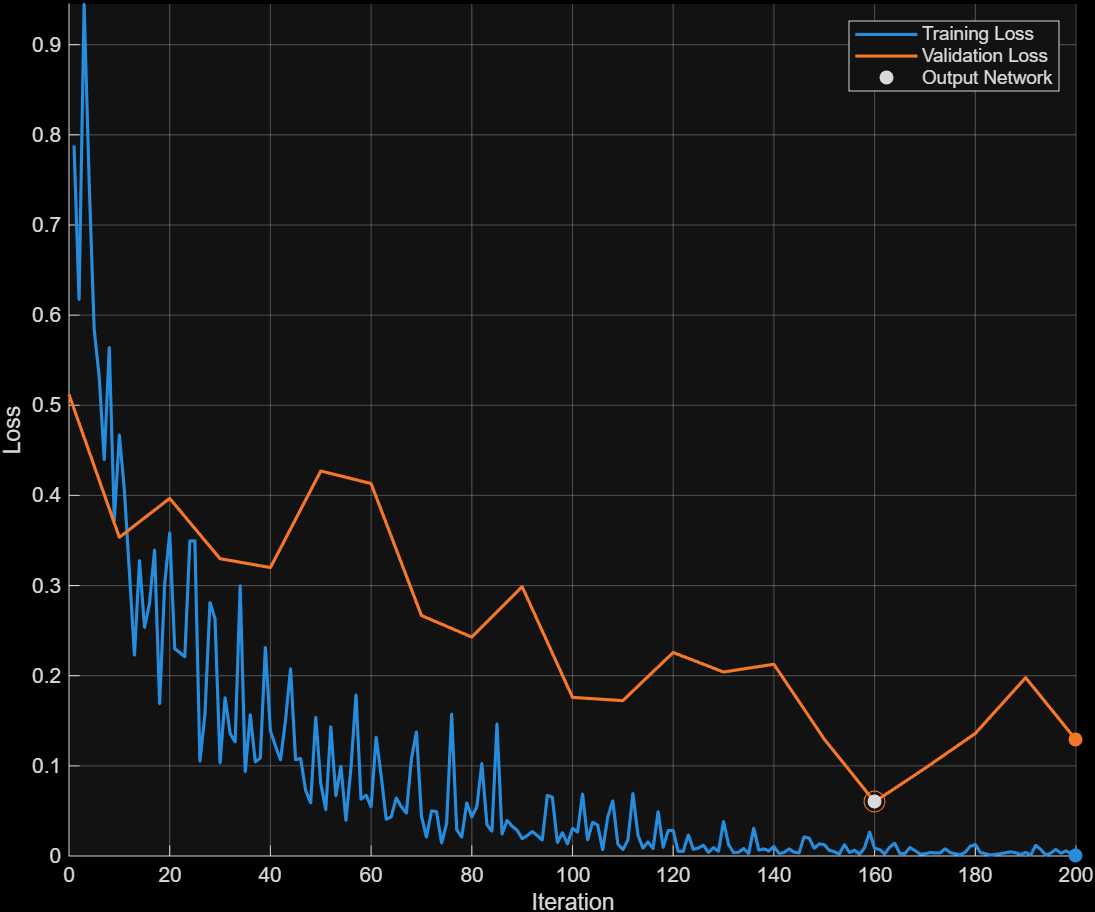

Confusion Matrix:

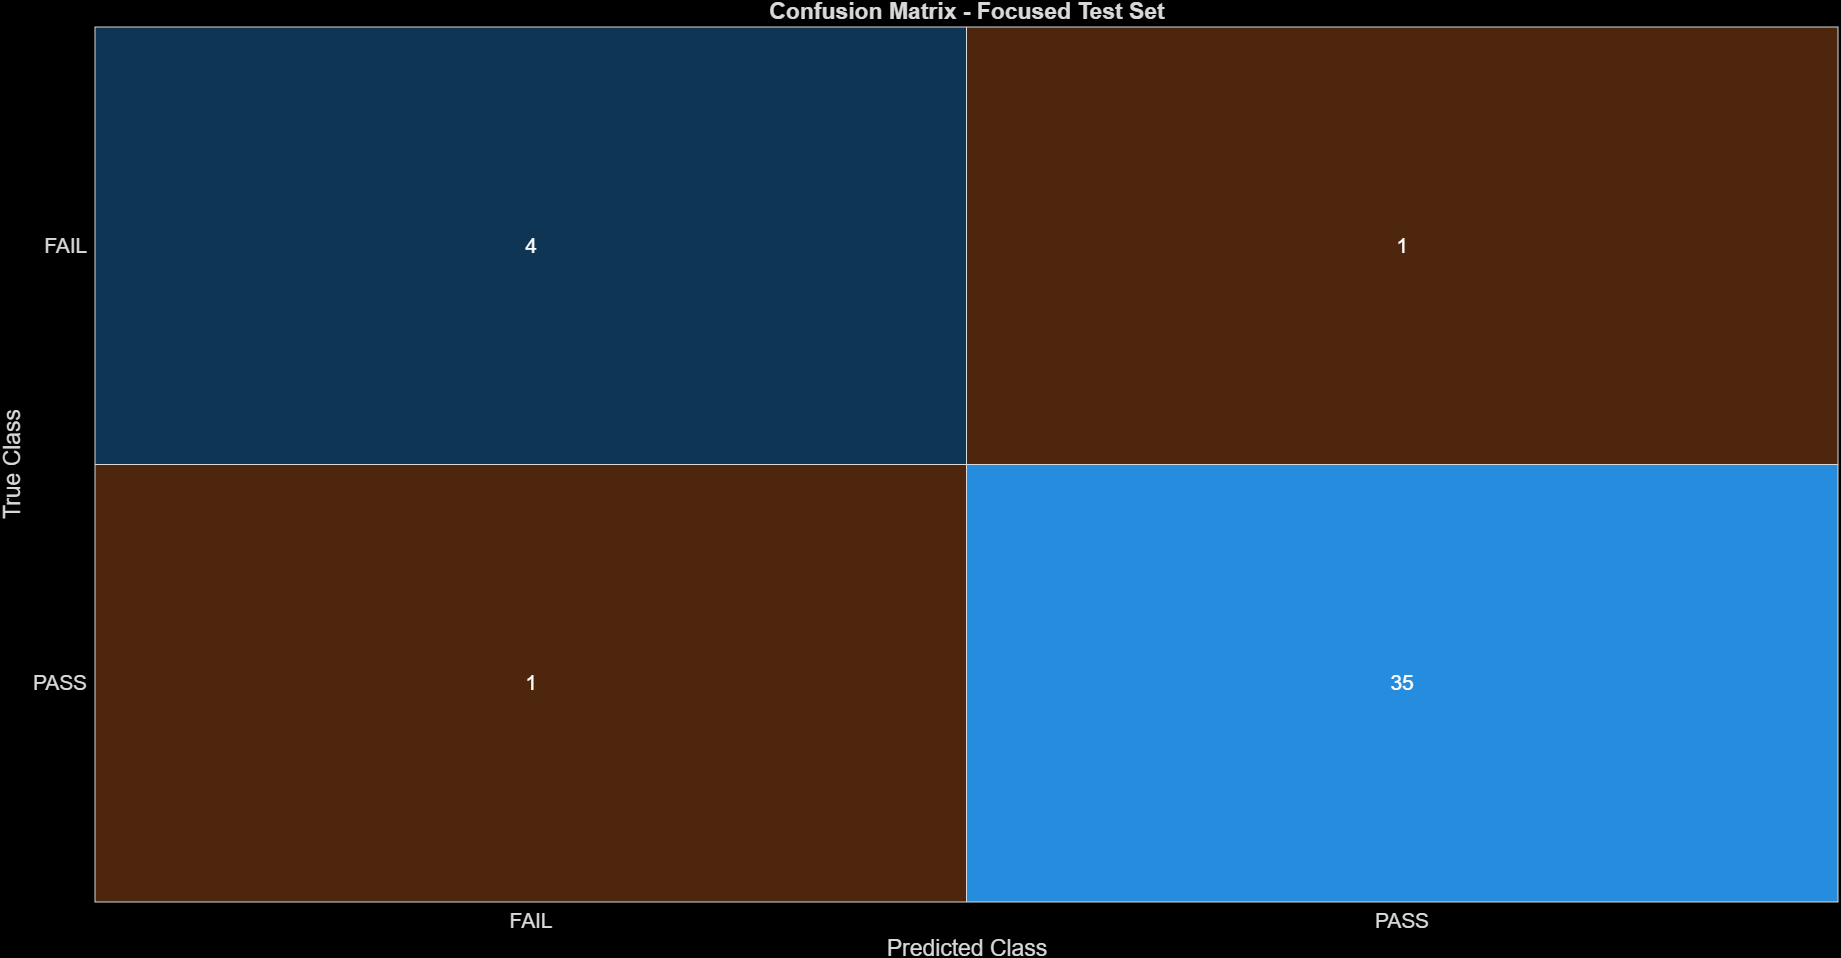

## 3.7 Transfer Learning Conclusion

    After experimenting and training on different training settings and shifting to a more focused dataset, our model peaked at a Test Accuracy of 95.12% with a very reasonable training time of 7 min 37 s. The F1 score, precision and recall were also consistent at 0.800. With this well performing neural network model, we now feel confident in creating a reliable hybrid inspection system that combines this AI with our classical vision pipeline.

Note:

- Initial training was done on all classes for a baseline experimentation in **'D_training_classifier_all_defects'**

- Final training was done on a focused subset in '**E_training_classifier'**

# 4. Hybrid Inspection System

## Task 4

    The completed inspection system combines the ResNet-18 classifier with the classical manipulated-front and scratch-neck evidence detectors. The AI classifier produces the primary PASS or FAIL prediction, while the classical branch provides quantitative metrics, visual evidence, and a conservative check when the AI is uncertain.

The complete single-image workflow is implemented in **inspectPart.**

## 4.1 Main Inspection Function

The **inspectPart** function connects all major parts of the project into '**F_run_inspection_suite**':

function [finalLabel, aiLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision]

 = inspectPart(inputImage)

It accepts one screw image and returns:

    This system architecture allows users to determine whether a rejection came directly from the AI or from the combination of an uncertain AI prediction and classical evidence.

## 4.2 Hybrid Workflow

Workflow Diagram:

The hybrid system is ordered such that:

- The input image is standardized using the shared preprocessing pipeline.

- The RGB image is passed to the trained ResNet-18 classifier to produce an AI prediction and confidence score. 

- The grayscale image is analyzed using the classical evidence extraction pipeline to produce metrics and evidence overlays.

- The AI prediction and classical evidence are combined in inspectPart.

- '**F_run_inspection_suite'** uses a confidence-based fusion rule to generate the final inspection decision.

## 4.3 Confidence-Based Hybrid Ruling

    The hybrid inspection system combines the AI classifier and classical evidence using a confidence-based fusion strategy. Rather than treating both inspection methods as equally weighted classifiers, each branch was assigned a specific role within the decision-making process:

- The ResNet-18 classifier serves as the primary inspection system because it learns complex visual features across multiple defect types and provides a confidence score with each prediction. 

- The classical image-processing pipeline provides visual evidence, but heavily relies on manually selected thresholds that can become sensitive to lighting changes, reflections, and normal manufacturing variation.

The fusion rule is implemented as:

`uncertainPass = aiLabel == "PASS" &&  confidenceScore < 0.90; `

`if aiLabel == "FAIL" `

`finalLabel = "FAIL"; `

`elseif uncertainPass && baselineDecision == "FAIL" `

`finalLabel = "FAIL"; `

`else `

`finalLabel = "PASS"; `

`end`

The if statement is summarized below:

## Decision Table For Hybrid System

This decision table establishes three key behaviors:

- **AI FAIL is always preserved**. When the AI predicts a defective component, the hybrid system accepts this decision regardless of the classical result. This prevents the rule-based system from overriding a confident defect prediction learned by the neural network.

- **High-confidence AI PASS remains PASS**. When the network predicts PASS with a confidence of 90% or greater, the component is accepted even if the classical detector identifies suspicious evidence. This limits unnecessary false rejects caused by conservative rule-based thresholds.

- **Low-confidence AI PASS** is verified using classical evidence. When the AI predicts PASS with confidence below 90%, the classical inspection result acts as a verification step. If both systems indicate the presence of suspicious features, the final decision becomes FAIL. Otherwise, the part is accepted.

    The selected 90% confidence threshold defines when the AI prediction is considered sufficiently reliable to stand on its own. This fusion system is effective as it combines the strengths of both inspection approaches.

## 4.4 Hybrid Inspection Demonstration

    Before evaluating the system on the complete test set, '**runHybridInspection', **an experimental script, was used to verify the full hybrid workflow on an individual screw image. We were able to use the this experimental script to test what worked and what was faulty for the fusion ruling before creating **'F_run_inspection_suite'**. The single image hybrid inspection tested the focused subset classes through image preprocessing, AI classification, classical evidence extraction, and confidence-based fusion, then displays the AI prediction, confidence score, classical decision, final hybrid decision, evidence metrics, and visual evidence overlay. 

    The completed hybrid inspection system was evaluated using **'F_run_inspection_suite'**. This script processes every image in the test set through inspectPart.m and records the AI, classical, and final hybrid decisions.

    The evaluation compares all three inspection approaches using confusion matrices, overall accuracy, yield, defect rate, precision, recall, and F1 score. It also identifies misclassified images and diagnoses which classical detector caused false rejects on good parts.

Focused Test Set:
    Label    Count
    _____    _____

    FAIL       5  
    PASS      36  


Good Image Classical Diagnosis
----------------------------------
Front Detector Only  : 0
Scratch Detector Only: 13
Both Detectors       : 1
Correctly Passed     : 22


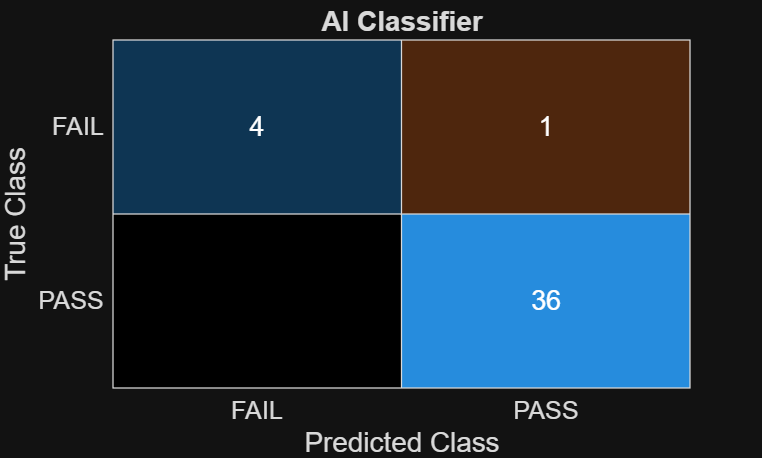

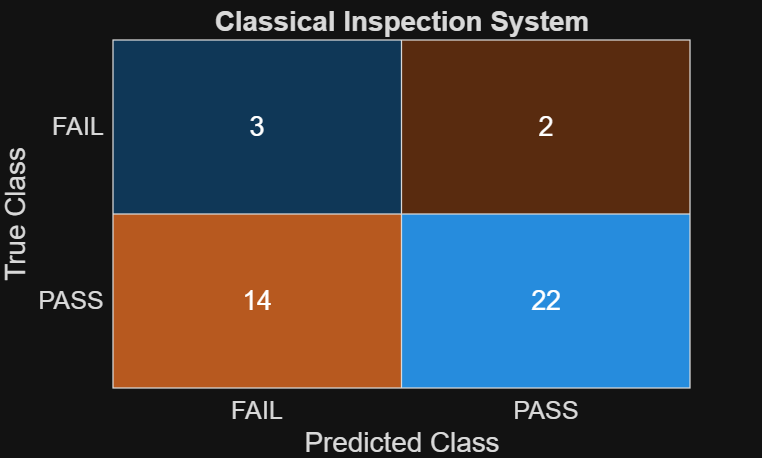

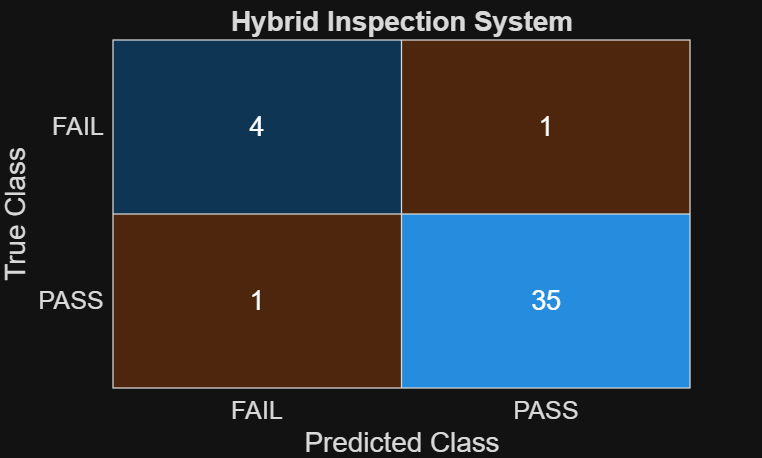


Inspection Results

Accuracy
-----------------------------
AI Accuracy         : 97.56%
Classical Accuracy  : 60.98%
Hybrid Accuracy     : 95.12%

AI Inspection Summary
----------------------------------
Passed Parts : 37
Failed Parts : 4
Yield         : 90.24%

Hybrid Inspection Summary
----------------------------------
Passed Parts : 36
Failed Parts : 5
Yield         : 87.80%


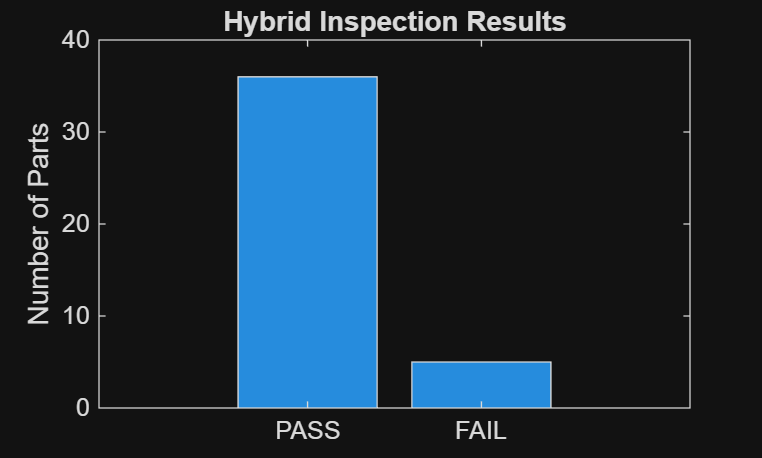

Hybrid Defect Rate: 12.20%


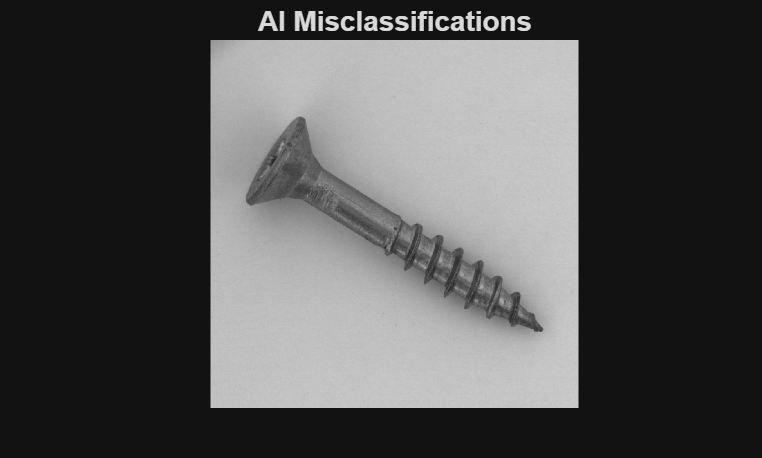

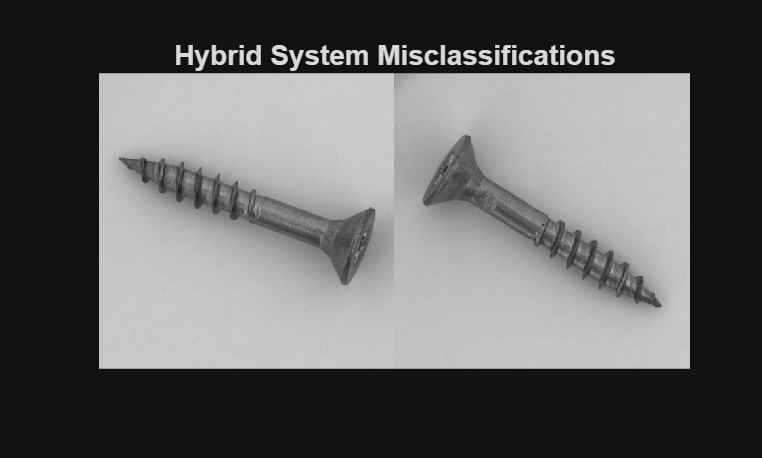


Hybrid Metrics
-----------------------------
Precision : 0.800
Recall    : 0.800
F1 Score  : 0.800


% Task 4: Evaluate Inspection System Performance
run("../scripts/F_run_inspection_suite")

# 5. Robust Evaluation

## Task 5

    Robustness testing evaluates how reliably the inspection system performs when image quality changes. In a real manufacturing environment, images may be affected by lighting differences, blur, vibration, camera noise, or changes in surface appearance. To simulate these conditions, the same held-out test set was evaluated under artificial and varying distortions. All testing was done in the **'G_test_robustness'** script.

## 5.1 Simulated Inspection Variations

    Five image conditions were evaluated:

- Original images were used as the baseline condition.

- Brightness variation simulated changes in illumination intensity.

- Contrast variation simulated differences between the screw and its background.

- Blur simulated camera focus errors or motion during image capture.

- Gaussian noise simulated electronic camera noise and image interference.

    The same distortion settings were applied to every image in the test set so that performance could be compared consistently across conditions.

## 5.2 Inspection Under Distorted Conditions

    Each modified image was passed through the complete **inspectPart** pipeline. The function produced separate decisions from the AI classifier and classical inspection branch, followed by the final fused hybrid decision.

    Using the same images and labels for every condition ensures that any performance change is caused by the simulated distortion rather than by a different test set.

## 5.3 Evaluation Metrics

   * Accuracy* measures the percentage of all images that were classified correctly. Although accuracy provides a useful overall summary, it may not fully describe inspection performance when the number of PASS and FAIL images is unbalanced.

    The *false-reject rate* measures how often an acceptable PASS part is incorrectly classified as FAIL. This metric is important in manufacturing because excessive false rejects can reduce production yield, increase unnecessary manual inspections, and cause acceptable products to be discarded.

    *Precision* measures how often predicted FAIL decisions represent actual defective parts. Low precision indicates that many acceptable parts are being rejected.

    *Recall *measures how many actual defective parts are successfully detected. Low recall indicates that defective parts are being incorrectly accepted.

    The *F1-score* combines precision and recall into one metric. It is useful when evaluating the balance between detecting defects and avoiding unnecessary false rejects.

## 5.4 Results and Performance Comparison

% Task 5: Test and Evaluate System Robustness
run("../scripts/G_test_robustness")

    The original-image condition produced the strongest overall performance. The AI classifier achieved 97.56% accuracy, while the hybrid system achieved 95.12% accuracy with a 2.78% false-reject rate.

    Brightness variation caused the largest decrease in hybrid performance. Hybrid accuracy decreased to 68.29%, while the false-reject rate increased to 36.11%. The hybrid recall remained at 1.00, meaning all defective images were detected, but the low precision of 0.278 shows that many acceptable screws were also incorrectly rejected. The brightness allowed reflections to mask existing edges and curves creating more error prone regions.

    Contrast variation also affected the inspection system significantly. The AI classifier remained relatively accurate at 92.68%, but classical accuracy decreased to 26.83%. As a result, the hybrid accuracy decreased to 78.05%, and the false-reject rate increased to 25.00%.

    Blur had a smaller effect on the system. The hybrid system maintained 92.68% accuracy and a 5.56% false-reject rate. This suggests that the learned AI features and classical measurements remained reasonably stable under the selected blur level.

    Under Gaussian noise, the hybrid system maintained 95.12% accuracy and produced no false rejects. However, recall decreased to 0.60, meaning that some actual defects were incorrectly classified as PASS. This result shows that a low false-reject rate does not automatically indicate strong inspection performance because missed defects must also be considered.

## 5.5 Comparison of AI, Classical, and Hybrid Performance

    All three inspection approaches were affected by image distortion, but the classical system was generally the most sensitive. The classical system depends on thresholding, edges, widths, slopes, masks, and intensity-based measurements. Changes in lighting and contrast directly affect these image properties, which can cause measurements to fluctuate due to our manually selected static, decision thresholds.

    The AI classifier was more stable under contrast and blur because it evaluates broader learned image features rather than relying on a small number of fixed measurements. However, its performance  decreased under brightness and noise, showing that the model is not completely independent of image quality.

    The hybrid system inherits strengths and weaknesses from both branches. Its rule-based fusion improves interpretability because a final FAIL decision can be traced to either the AI prediction or the classical evidence. However, when the classical branch becomes overly sensitive to distorted images, it can override an uncertain but correct AI PASS decision. This explains why the hybrid false-reject rate increased sharply under brightness and contrast variation.

## 5.6 Robustness Discussion

    The results show that controlled illumination is especially important for this inspection system. Brightness and contrast variation caused the greatest performance loss because they strongly affected the classical measurements used in the fusion decision.

The hybrid design provides more traceability than solely using the AI classifier alone because its decisions can be supported by evidence overlays, extracted metrics, confidence values, and rule-based decisions. However, the fusion logic must be calibrated carefully. A highly sensitive classical branch can improve defect detection but may also reject too many acceptable parts.

    Future work could incorporate an adaptive fusion strategy that dynamically adjusts the AI confidence threshold under varying imaging conditions. This would allow the hybrid system to reduce its reliance on the more sensitive classical inspection branch when image quality degrades, potentially reducing false rejects while maintaining reliable defect detection. Additionally, this system can be further improved with lighting normalization, more adaptive thresholds, and more training with augmentation.

# Conclusion